cd('C:\Users\user\Dropbox\projekte\Lehrveranstaltungen\MA\Simulations\matlab\flexible_arm')

# Modelling approach for flexible robot arm

Based on: **[MoranEstikoTanakaHayase1996]** $\text{H}_\infty$* Control of a flexible arm considering motor  dynamics and optimum sensor location *

## Problem setup

Basic assumptions:

- small deflections $\theta_d<<1\Rightarrow w(L)\approx\theta_d$

- Euler-Bernoulli beam

System sketch:

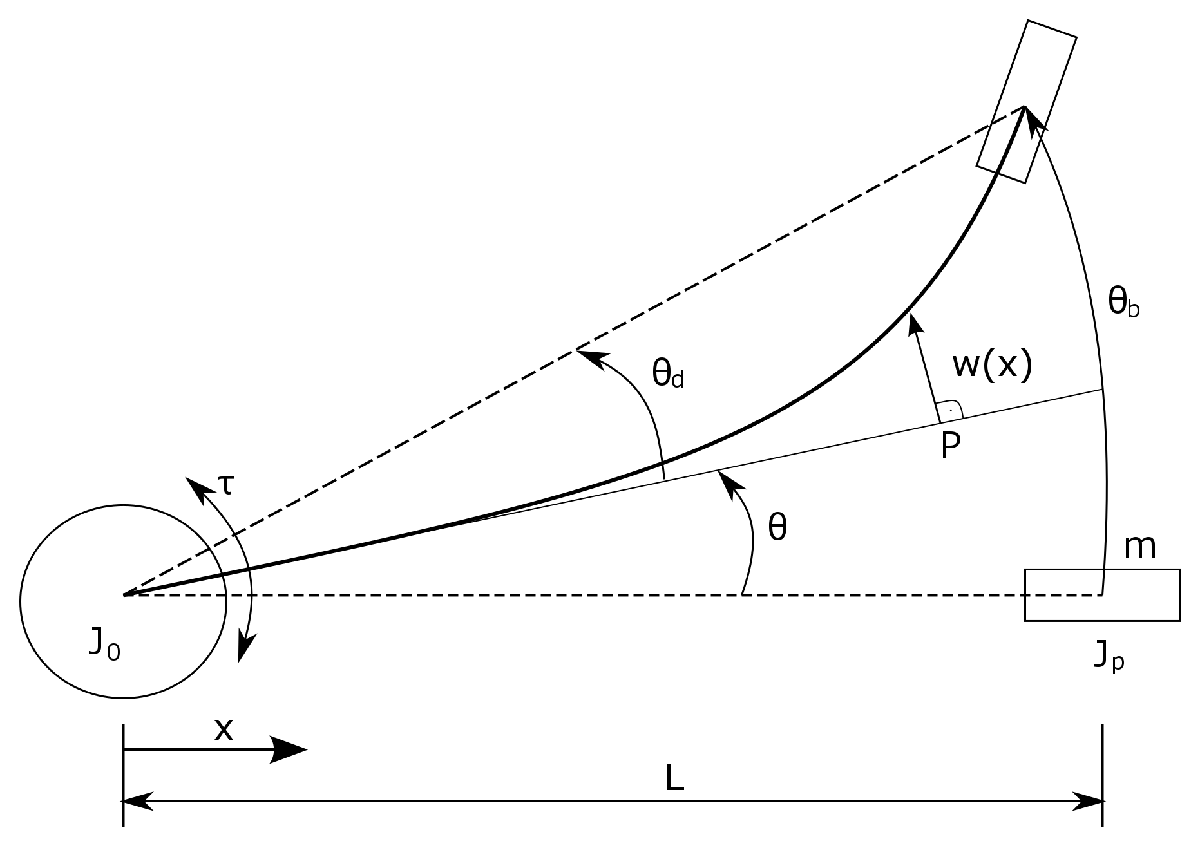

QUESTION: The x axis aligned to nominal beam?

## Distributed parameter model

Slewing arm motion:


$$J_r\ddot{\theta}(t)+\rho A\int_0^Lx\ddot{w}(x,t)dx+mL\ddot{w}(L,t)=r(t)$$



$$EI\,w''''(x,t)+\rho A\left(\ddot{w}(x,t)+x\ddot\theta(t)\right)=0$$


Boundary condtions:


$$w(0,t)=w'(0,t)=0
$$



$$w''(L,t)=0$$



$$EI\,w'''(L,t)=m\big(L\ddot\theta(t)+\ddot w(L,t)\big)$$


QUESTION: Wrong unit in last BC?

## PDE solution

Seperation of variables approach:


$$w(x,t)=:\Phi(x)q(t)\\
\theta(t)\quad=:\eta(t)+p\,q(t)$$


Comments: $q\rightarrow\theta_d$ (angle deviation due to flexibility), $\eta\rightarrow\theta
$ (nominal angle)

QUESTION: Constant$p$?

Free motion system: $r=0$

Assumption: no significant torque produced by deflection


$$\text{1st dyn. equ.}\quad\Rightarrow\quad J_rp\ddot{q}(t)+\rho A\int_0^Lx\Phi(x)dx\,\ddot q(t)+mL\Phi(L)\ddot{q}(t)=0$$



$$\text{plug into 1st dyn. equ.}\quad\Rightarrow\quad J_r\ddot\eta=0$$


Plugging approach into 2nd dynamic equation:


$$\Phi''''(x)q(t)+\frac{\rho A}{EI}\left(\Phi(x)\ddot{q}(t)+x\ddot\eta(t)+px\ddot q(t)\right)=0$$



$$\ddot\eta=0\quad\Rightarrow\quad\frac{EI}{\rho A}\,\frac{\Phi''''(x)}{px+\Phi(x)}=-\frac{\ddot q(t)}{q(t)}\overset{!}{=}\text{const}=:\omega^2$$


where $\omega>0
$ to obtain a reasonable hyperbolic solution. Thus the following ODEs hold:


$$\ddot q(t)+\omega^2q(t)=0\\
\Phi''''(x)-\frac{\rho A}{EI}\omega^2\,\big(px+\Phi(x)\big)=0$$


The equation for $\Phi(x)$ can be solved analyitically by including the boundary conditions:


$$\Phi(x)=\left(\cos(\beta xq)-c_1\sin(\beta x)-\cosh(\beta x)+c_2\sinh(\beta x)-2\alpha\beta^{-2}x\right)\cdot C_i$$


where 


$$c_1=\frac{\cos(\beta L)+\cosh(\beta L)-2\alpha\beta^{-3}\sinh{\beta L}}{\sin(\beta L)+\sinh(\beta L)}\\\\

c_2=\frac{\cos(\beta L)+\cosh(\beta L)+2\alpha\beta^{-3}\sinh{\beta L}}{\sin(\beta L)+\sinh(\beta L)}$$


with the constants $\alpha=\frac{\rho A}{J_0}$ and $\beta^4=\frac{\rho A\omega^2}{EI}$. An infinite number of $\beta_i$ satisfies the BC, each corresponding to one flexible mode.

Expansion of global solution $\forall x\in[0,L],t\geq0$:


$$\theta(t)=\eta(t)+\overset{\infty}{\underset{i=1}{\sum}}p_iq_i(t)\,,\quad w(x,t)=\overset{\infty}{\underset{i=1}{\sum}}\Phi_i(x)q_i(t)$$


Forced motion equations: $r=r(t)$

After having solved the free motion eigen-value problem for mode function $\Phi(x)$, its orthogonality properties are uses for solving the forced motion equations:


$$\text{Rigid body:}\qquad J_r\ddot\eta=r(t)\\
\text{Flexible body:}\quad \ddot q_i(t)+\omega_i^2q_i(t)=k_ir(t) $$


where 


$$k_i=\frac{p_i+\frac{m\Phi_i(L)}{Jr}}{\overset{\infty}{\underset{j=1}{\sum}}\big[\delta_{ij}-m\Phi_i(L)(p_jL+\Phi_j(L))\big]}$$


QUESTION: Is it the same $\Phi_i$ like above? What is $\delta_{ij}$? How derived the constants $k_i$?

## Motor-arm composition

Taking the SC motor dynamics into account:


$$r(t)=\frac{K_t}{R_a}\,\big(u(t)-K_e\dot{\theta}(t)\big)$$


Combining this with the rigid and flexible body equations, and considering viscosity ($D,\zeta$ respectively) the ODE system becomes:


$$J_r\ddot\eta(t)+\left(\frac{K_tK_e}{R_a}+D\right)\dot\eta(t)+\left(\frac{K_tK_e}{R_a}\overset{\infty}{\underset{j=1}{\sum}}p_j\right)\dot q_i(t)=\frac{K_t}{R_a}\,u(t) \\\\

\ddot q_i(t)+\left(\frac{K_tK_e}{R_a}\overset{\infty}{\underset{j=1}{\sum}}(k_jp_j+2\zeta_j\omega_j)\right)\dot q_i(t)+\omega_i^2q_i(t)=k_i\frac{K_{pa}K_t}{R_a}u(t)$$


where all modes $i=1,\ldots,\infty$ have to be considered.

The system then can be expressed in the infinite dimensional state space form:


$$\dot x(t)=Ax(t)+Bu(t)$$


with the state space vector


$$x:=\left[\eta\,,\,\dot\eta\,,\,q_1\,,\,\dot q_1\,,\,q_2\,,\,\dot q_2\,,\,\ldots\,,\,q_\infty\,,\,\dot q_\infty\right]^T$$


For numerical implementation a finite number of modes $N$ has to be selected with a neglection of higher order dynamics.

# Numerical test of solution

## Parameters

Flexible arm deterministic parameters:

% Arm-payload:
E = 1.96e11;     % [N/m^2]
I = 2.08e-12;    % [m^4]
A = 25e-6;       % [m^2]
L = 0.25;        % [m]
Th = 1e-3;       % [m]
rho = 10.667e3;  % [kg/m^3]
m = 0.2;         % [kg]
J0 = 1e-3;       % [kg*m^2]
% Motor-hub:
Ra = 1.3;        % [ohm]
Kt = 0.0735;     % [N*m/A]
Ke = 0.0735;     % [V*s/rad]
D = 1e-4;        % [Nms/rad]
Kpm = 0.8185;    % [V/rad]
Kpa = 10;        % [-]
Ksg = 2500;      % [V]

Mode related parameter assumptions:

N = 100; % approximation order
zeta = D*ones(1,N);

## Mode function

Revise equation:


$$\Phi''''(x)-\frac{\rho A}{EI}\omega^2\,\big(px+\Phi(x)\big)=0$$


with boundary condition derived from their validity for all times:


$$\Phi(0)=0\,,\quad
\Phi'(0)=0\,,\quad
\Phi''(L)=0$$


The last BC can be simplified by using results from the seperation of variables step. Pluggin in:


$$EI\,\Phi'''(L)q(t)=mL\left(\ddot\eta(t)+p\ddot q(t)\right)+m\Phi(L)\ddot q(t)$$



$$\overset{\ddot\eta=0}{\Rightarrow}\quad \frac{EI}{m}\frac{\Phi'''(L)}{Lp+\Phi(L)}=\frac{\ddot q(t)}{q(t)}\,\,\,\overset{\text{SoV}}{=}\,\,\,-\omega^2\\
\Rightarrow\quad \Phi'''(L)+\omega^2\frac{m}{EI}\big(Lp+\Phi(L)\big)=0$$


Solution of mode function $\Phi
$. Define ODE boundary value problem:

% Symbolic definitions:
syms phi(x)
omega = sym('omega','real'); p = sym('p','real'); % real parameters
Dphi=diff(phi,x); D2phi=diff(phi,x,2); D3phi=diff(phi,x,3);
% ODE and BC:
phieqn = diff(phi,x,4) - rho*A/(E*I)*omega^2*(p*x+phi(x)) == 0;
bc = [phi(0)==0, Dphi(0)==0, D2phi(L)==0, ...
    E*I*D3phi(L)+omega^2*m*(L*p+phi(L))==0];
% Solver:
phisol = dsolve(phieqn); expand(phisol)
phisol1 = dsolve(phieqn,bc);
phifun = matlabFunction(subs(phisol1,p,1),'Vars',{x,omega});
% Plot solution for test parameters:
X = 0:0.005:L;
Omega = [10 100 500 1000 2000];
figure; hold on
for i=1:length(Omega)
    plot(X,phifun(X,Omega(i)))
end
title('Mode function test plot')
legend('\omega=10','\omega=100','\omega=500','\omega=1000','\omega=2000')
grid; xlabel('x'); ylabel('\Phi'); hold off

# Alternative computation approach

Based on: **[DeLuca2014]** *Flexible Robots (Encyclopedia of Systems and Control)*

## Problem setup

Basic assumptions:

- uniform density $\rho$

- small deformations

- Euler-Bernoulli beam $\Rightarrow$ rotational beam intertia neglected

- HERE: CoM effects neglected (difference?)

System sketch:

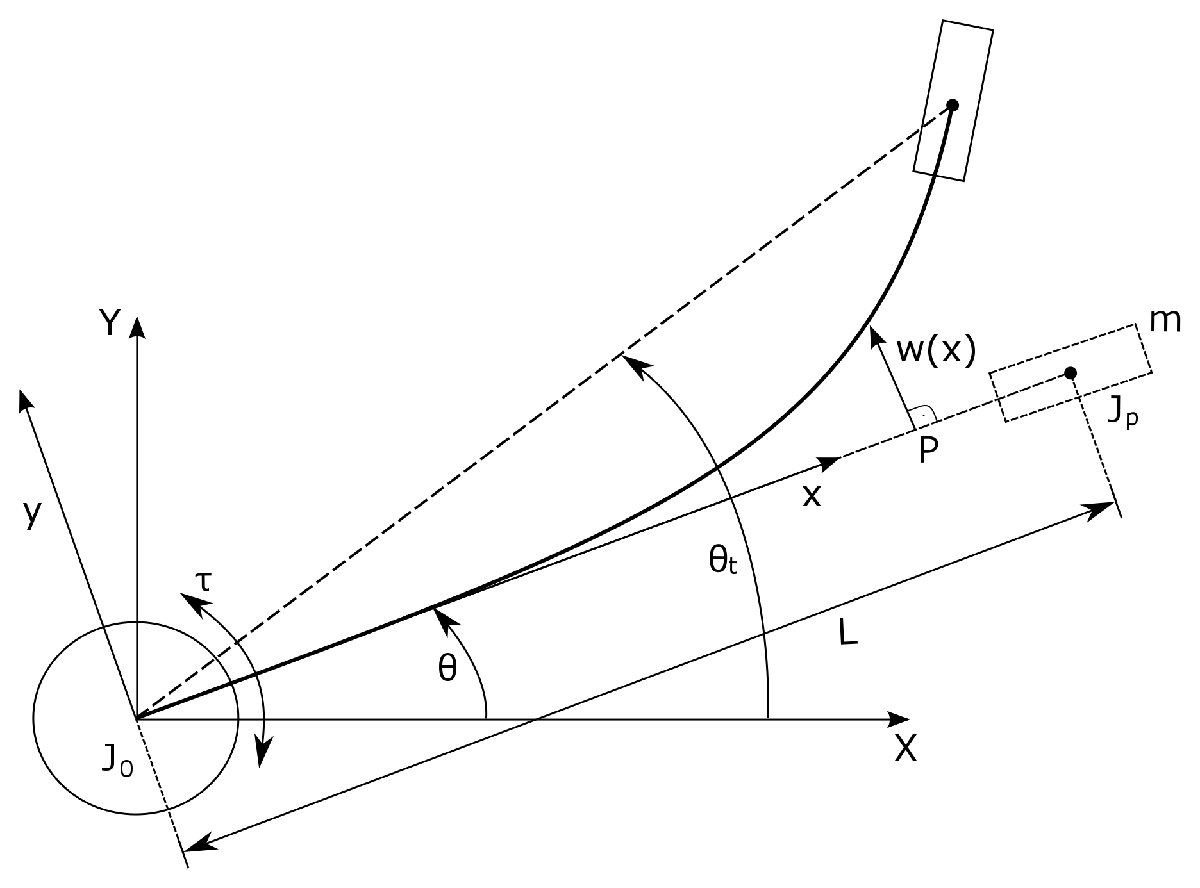

where

- Total moment of inertia: $J=J_0+\frac{\rho L^3}{3}+J_P+mL^2$ 

- Young modulus cross-section inertia: $EI$

- Bending deformation variable: $w(x,t)$

Flexible arm deterministic parameters:

% Arm-payload:
E = 1.96e11;     % [N/m^2]
I = 2.08e-12;    % [m^4]
L = 0.25;        % [m]
rho = 10.667e3;  % [kg/m^3]
m = 0.2;         % [kg]
J0 = 1e-3;       % [kg*m^2]
Jp = 1e-4;       % [kg*m^2]
J = J0+rho*L^3/3+Jp+m*L^2;

Mode related parameter assumptions:

N = 5; % approximation order
zeta = 1e-4*ones(1,N);

## Preparation of simulation

General mode function solution:


$$\Phi(x)=C_1\sin(\beta x)+C_2\cos(\beta x)+C_3e^{\beta x}+C_4e^{-\beta x}\,,\quad\beta^4=\frac{\rho\omega^2}{EI}$$


with boundary conditions $(I.)$:


$$\Phi(0)=0\\
EI\,\Phi''(0)+J_0\,\omega^2\Phi'(0)=0\qquad\text{(balance of moments at base)}\\
EI\,\Phi''(L)-J_P\,\omega^2\Phi'(L)=0\qquad\text{(balance of moments at tip)}\\
EI\,\Phi'''(L)+m\omega^2\Phi(L)=0\qquad\text{(balance of shear forces at tip)}$$


and easier alternative boundary conditions $(II.)$:


$$\Phi(0)=\Phi'(0)=0\\
\Phi''(L)=\Phi'''(L)=0$$


Then by plugging the solution into the BC, the following system equations is obtained:

% Variable dependence:
beta = sym('beta','positive');
omega = sqrt(beta^4*E*I/rho);
% Building the characteristic matrix:
% A = [0 1 1 1;
%     J0*omega^2*beta -E*I*beta^2 E*I*beta^2+J0*omega*beta E*I*beta^2-J0*omega*beta
%     -E*I*beta^2*sin(beta*L)-Jp*omega^2*beta*cos(beta*L) -E*I*beta^2*cos(beta*L)+Jp*omega^2*beta*sin(beta*L) ...
%     E*I*beta^2*exp(beta*L)-Jp*omega^2*beta*exp(beta*L) E*I*beta^2*exp(-beta*L)+Jp*omega^2*beta*exp(-beta*L);
%     -E*I*beta^3*cos(beta*L)+m*omega^2*sin(beta*L) E*I*beta^3*sin(beta*L)+m*omega^2*cos(beta*L) ...
%     E*I*beta^3*exp(beta*L)+m*omega^2*exp(beta*L) -E*I*beta^3*exp(-beta*L)+m*omega^2*exp(-beta*L)];
A = [0 1 1 1;
    beta 0 beta -beta;
    -beta^2*sin(beta*L) -beta^2*cos(beta*L) beta^2*exp(beta*L) beta^2*exp(-beta*L);
    -beta^3*cos(beta*L) beta^3*sin(beta*L) beta^3*exp(beta*L) -beta^3*exp(-beta*L)]
% Plot roots:
char = matlabFunction(det(A));
bvec = 0:0.01:8;
figure; plot(bvec,char(bvec));
grid; xlabel('\beta'); ylabel('det(A)'); title('Transcendental equation check')
% Finding zeros:
bsol = 0; % storage
bsmp = 1:1:850; % samples
epsilon = 1e-3; % numeric accuracy
for i=1:length(bsmp)
    tmp = fzero(char,bsmp(i));
    if (tmp>bsol(end)+epsilon)
        bsol = [bsol tmp];      
    end
end
figure; subplot(2,1,1); plot(bsol,'--gs')
grid; ylabel('\beta_0'); title('Characteristic roots')
subplot(2,1,2); plot(diff(bsol),'--bs')
grid; xlabel('iter'); ylabel('\Delta\beta_0'); title('Root distances')
% Check characterisitc matrix rank: (null space check)
Af = matlabFunction(A); % A(beta)
figure; hold on
for j=1:30
    plot(bsol(j),rank(Af(bsol(j))),'bs')
end
grid; xlabel('\beta_0'); ylabel('rank(A)'); title('Characteristic matrix rank'); hold off

Observation: rank decrease over long term $\rightarrow$ just numerical issue at beginning?

% Construction of eigen components:
omega = sqrt(E*I/rho*bsol.^4);
figure; plot(omega,'--rs')
grid; xlabel('iter'); ylabel('\omega_i [rad/s]'); title('Eigenfrequencies')

After identifying the eigen characteristics the modal function can be obtained. It is the solution to:


$$\Phi_i''''(x)-\frac{\rho}{EI}\,\omega_i^2\Phi_i(x)=0$$


in combination with the upper BC. Remember the general solution of the form:


$$\Phi(x)=\left[\sin(\beta x),\cos(\beta x),e^{\beta x},e^{-\beta x}\right]\cdot P$$


with parameter vector $P=[C_1,C_2,C_3,C_4]^T$. With respect to the characteristic matrix $\mathcal{A}(\beta)$ and the transcendental roots $\beta_i$ its kernel is defined as:


$$\mathcal{N}_i:=\ker(\mathcal{A}(\beta_i))
=\text{span}\underset{\mathcal{BN}_i}{\underbrace{\big\{P_1,\ldots,P_{m_i}\,|\,\mathcal{A}(\beta_i)P_j=0,||P_j||=1,k\neq l:P_k\perp P_j\big\}}}$$


where $m_i$ determines the dimension of the null space and the stated set of an orthonormal basis $\mathcal{BN}_i$. Then the particular modal solutions are the following:


$$\Phi_i(x)=\left[\sin(\beta_i x),\cos(\beta_i x),e^{\beta_i x},e^{-\beta_i x}\right]\cdot \left(\overset{m_i}{\underset{j=1}{\sum}}P_j\right)\,,\quad P_j\in\mathcal{BN}_i$$


for $i=1,\ldots,N$ and approximation order $N$. These solutions are uniquely defined up to a constant factor.

QUESTION: really this kind of linear combination?

% Eigen function:
h = 1e-2; % step size
X = 0:h:L;
phiarr = zeros(N,length(X));
for i=1:N
    be = bsol(i+1); % exclude trivial solution beta=0
    BNi = null(Af(be));
    Psum = sum(BNi,2);
    tmpfcn = @(x)(Psum(1)*sin(be*x)+Psum(2)*cos(be*x)+Psum(3)*exp(be*x)+Psum(4)*exp(-be*x));
    phiarr(i,:) = tmpfcn(X);
end
% Visualize:
figure; hold on
for i=1:5
    plot(X,phiarr(i,:))
end
legend('i=1','i=2','i=3','i=4','i=5')
grid; xlabel('x'); ylabel('\Phi_i(x)'); title('Eigen modes'); hold off
% Check boundary conditions:
figure
subplot(2,2,1); hold on
for i=1:5
    plot(X,phiarr(i,:))
end
grid; title('\Phi(0)=0'); hold off
subplot(2,2,2); hold on
for i=1:5
    plot(X(2:end),diff(phiarr(i,:))/h)
end
grid; title('D\Phi(0)=0'); hold off
subplot(2,2,3); hold on
for i=1:5
    plot(X(3:end),diff(phiarr(i,:),2)/h^2)    
end
grid; title('D2\Phi(L)=0'); hold off
subplot(2,2,4); hold on
for i=1:5
    plot(X(4:end),diff(phiarr(i,:),3)/h^3)
end
grid; title('D3\Phi(L)=0'); hold off
%REMARK: apropriate higher order derivatives?

## Free evolution case

Resulting system dynamics:


$$J\ddot\Theta(t)=0\\
\ddot\delta_i(t)+\omega_i^2\delta_i(t)=0$$


for state space vector:


$$z=\left[\theta\,,\,\dot\theta\,,\,\delta_1\,,\,\dot\delta_1\,,\,\ldots\,,\,\delta_N\,,\,\dot\delta_N\right]^T$$


% System dynamics:
omblx = kron(diag(-omega(2:N+1).^2),[0 0;1 0]) + kron(eye(N),[0 1;0 0]);
Adyn = blkdiag([0 1;0 0],omblx);
homdyn = @(t,z)(Adyn*z);
% Initial conditions & solver:
z0 = [0 0 kron(exp(-[1:N]),[1 0])]'; % excitation by IC
[time,zsol] = ode45(homdyn,[0:0.2:10],z0);
% Test:
figure; plot(time,zsol(:,3:2:end-1))
legend('\delta_1(t)','\delta_2(t)','\delta_3(t)','\delta_4(t)','\delta_5(t)')
grid; xlabel('time t'); ylabel('z_j(t)'); title('Dynamic trajectories'); hold off

Overall system composition:


$$w(x,t)=\overset{\infty}{\underset{i=1}{\sum}}\Phi_i(x)\delta_i(t)\approx\overset{N}{\underset{i=1}{\sum}}\Phi_i(x)\delta_i(t)$$


% 3D deformation plot:
delta = zsol(:,3:2:end-1)';
time = time';
w = zeros(length(time),length(X));
for j=1:length(time) % build over time
    tmpcol = sum(diag(delta(:,j))*phiarr);
    w(j,:) = tmpcol;
end
figure; surfl(X,time,w); %shading flat
xlabel('x'); ylabel('t'); zlabel('w(x,t)'); title('Bending deformation')

TODO: implement animation

## Excitation of system by torque

For an input signal $\tau(t)$ the dynamics are extended to:


$$J\ddot\Theta(t)=\tau(t)\\
\ddot\delta_i(t)+\omega_i^2\delta_i(t)=\Phi_i'(0)\tau(t)$$


again with state space vector:


$$z=\left[\theta\,,\,\dot\theta\,,\,\delta_1\,,\,\dot\delta_1\,,\,\ldots\,,\,\delta_N\,,\,\dot\delta_N\right]^T$$


PROBLEM: $\Phi_i'(0)=0\,\forall i$ due to BC

Check PDE conditions on result:

...

# General approach

addpath functions

Based on: **[Kanoh1991]** *Distributed parameter models of flexible robot arms*

## Problem setup

Linearized dynamic equations:


$$e\ddot\theta(t)+b\int^1_0x\ddot y(x,t)dx+bc\ddot y(1,t)=u(t)\\
y''''(x,t)+x\ddot\theta(t)+\ddot y(x,t)=0$$


Alternatively: multiply 1st equ. by $bx$ & integrate, substitute in 2nd equ.


$$\Rightarrow\quad\ddot\theta(t)-by''(0,t)=u(t)$$


Respective boundary conditions:


$$y(0,t)=0\\
y'(0,t)=0\\
y''(1,0)=0\\
y'''(1,t)=c\big(\ddot\theta(t)+\ddot y(1,t)\big)$$


COMMENT: In the following a comparison between analytic (paper) and numeric mehtods is made.

% Parameters: (dimensionless)
b = 1;
c = 1;
e = 1;

## Constrained mode method

Assumption: $\ddot\theta(t)=0\,\forall t\geq0$


$$\Rightarrow\quad y''''(x,t)+\ddot y(t)=0\\
\text{s.t.}\quad y(0,t)=y'(0,t)=y''(1,t)=0\\
\qquad y'''(1,t)=c\ddot y(1,t)$$


Ansatz:


$$y(x,t)=\psi(x)r(t)$$


Resulting in (standard SoV):


$$\ddot r(t)+\Omega^2r(t)=0\\
\psi''''(x)-\Omega^2\psi=0$$


with BC:


$$\psi(0)=\psi'(0)=\psi''(1)=0\\
\psi'''(1)+c\Omega^2\psi(1)=0$$


Solution form:


$$\psi(x)=A\sin(\xi x)+B\cos(\xi x)+C\sinh(\xi x)+D\cosh(\xi x)\\
\qquad=\frac{1}{2\xi^3}\big[\xi\big(\cosh(\xi x)-\cos(\xi x)\psi''(0)\big)+\big(\sinh(\xi x)-\sin(\xi x)\psi'''(0)\big]$$


with $\xi^4:=\Omega^2$.

% Transcendental equation comparison:
syms xi
charcalc = @(xi)(1+cos(xi).*cosh(xi)-c.*xi.*(sin(xi).*cosh(xi)-cos(xi).*sinh(xi)));
A = [0 1 0 1;
    xi 0 xi 0;
    -xi^2*sin(xi) -xi^2*cos(xi) xi^2*sinh(xi) xi^2*cosh(xi);
    -xi^3*cos(xi)+xi^4*c*sin(xi) xi^3*sin(xi)+xi^4*c*cos(xi) xi^3*cosh(xi)+xi^4*c*sinh(xi) xi^3*sinh(xi)+xi^4*c*cosh(xi)]

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 1\\ \xi & 0 & \xi & 0\\ -\xi^{2}\,\sin\left(\xi \right) & -\xi^{2}\,\cos\left(\xi \right) & \xi^{2}\,\sinh\left(\xi \right) & \xi^{2}\,\cosh\left(\xi \right)\\ \xi^{4}\,\sin\left(\xi \right)-\xi^{3}\,\cos\left(\xi \right) & \xi^{4}\,\cos\left(\xi \right)+\xi^{3}\,\sin\left(\xi \right) & \xi^{3}\,\cosh\left(\xi \right)+\xi^{4}\,\sinh\left(\xi \right) & \xi^{4}\,\cosh\left(\xi \right)+\xi^{3}\,\sinh\left(\xi \right) \end{array}\right)$$

char = matlabFunction(det(A));
epsilon = 1e-3; % numeric accuracy
bsmp = 1:1:200; % samples
bsol1 = 0; % storage
for i=1:length(bsmp)
    tmp = fzero(char,bsmp(i));
    if (tmp>bsol1(end)+epsilon)
        bsol1 = [bsol1 tmp];      
    end
end
bsol2 = 0; % storage
for i=1:length(bsmp)
    tmp = fzero(charcalc,bsmp(i));
    if (tmp>bsol2(end)+epsilon)
        bsol2 = [bsol2 tmp];      
    end
end
mean(abs(bsol1-bsol2)) % check similarity (=0?)

ans = 0.0041

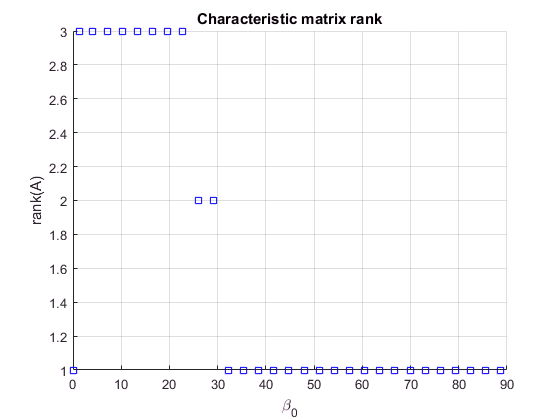

Af = matlabFunction(A); % A(xi)
figure; hold on
for j=1:30
    plot(bsol1(j),rank(Af(bsol1(j))),'bs')
end
grid; xlabel('\beta_0'); ylabel('rank(A)'); title('Characteristic matrix rank'); hold off

COMMENT: rank $<3$ because of bad conditioned matrices (numerics)

% Eigenfunction construction by numerical calculation:
h = 2e-2; % step size
N = 9; % degree of discretizitaion
X = 0:h:1;
psiarr = zeros(N,length(X));
for i=1:N
    be = bsol1(i+1); % exclude trivial solution beta=0
    P = null(Af(be));
    if (size(P,2)==1)
        tmpfcn = @(x)(P(1)*sin(be*x)+P(2)*cos(be*x)+P(3)*sinh(be*x)+P(4)*cosh(be*x));
        tmpnorm = sqrt(integral(@(x)(tmpfcn(x).^2),0,1));
        psiarr(i,:) = tmpfcn(X)/tmpnorm; % normalized (for p=1)
    else        
        disp(strcat('Ill conditioned characteristic matrix (rank<3) at xi=',...
        num2str(be),', i=',num2str(i+1),'.'))
    end
end

Ill conditioned characteristic matrix (rank<3) at xi=25.9371, i=10.


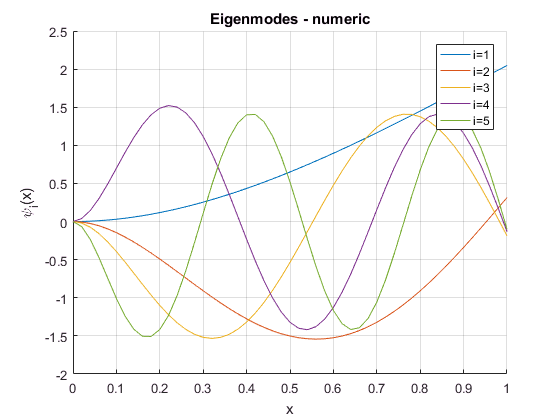

figure; hold on
for i=1:5
    plot(X,psiarr(i,:))
end
legend('i=1','i=2','i=3','i=4','i=5')
grid; xlabel('x'); ylabel('\psi_i(x)'); title('Eigenmodes - numeric'); hold off

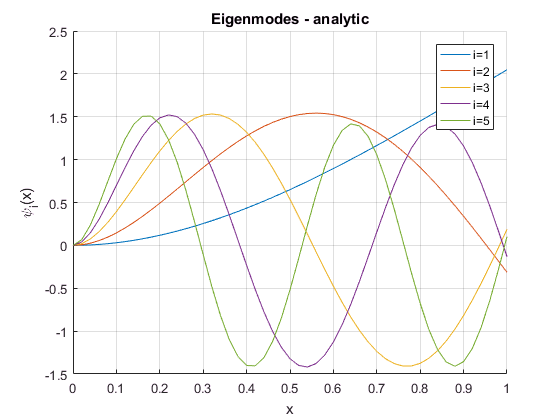

% Eigenfunction by analytic considerations:
psians = @(x,xi)((sinh(xi)+sin(xi))*(cosh(xi*x)-cos(xi*x))-(cosh(xi)+cos(xi))*(sinh(xi*x)-sin(xi*x)));
figure; hold on
for i=1:5
    be = bsol2(i+1);
    tmpnorm = sqrt(integral(@(x)(psians(x,be).^2),0,1));
    plot(X,psians(X,be)/tmpnorm)
end
legend('i=1','i=2','i=3','i=4','i=5')
grid; xlabel('x'); ylabel('\psi_i(x)'); title('Eigenmodes - analytic'); hold off

COMMENT: Obivously equal normalized mode functions in both cases, defined up to the sign.

Form of total beam deformation:


$$y(x,t)=\overset{\infty}{\underset{i=1}{\sum}}\psi_i(x)r_i(t)$$


Plugging into dynamic equations results in:


$$\ddot\theta(t)-b\overset{\infty}{\underset{i=1}{\sum}}\psi_i''(0)r_i(t)=u(t)\\
\overset{\infty}{\underset{i=1}{\sum}}\psi_i''''(x)r_i(t)+x\ddot\theta(t)+\overset{\infty}{\underset{i=1}{\sum}}\psi_i(x)\ddot r_i(t)=0$$


Modulating the 2nd equ. with $\psi_j(x)$ over $[0,1]$ and using orthonormality of eigenfunctions leads to:


$$\ddot r_j(t)+\Omega_j^2r_j(t)+\underset{=m_j:={\psi_j''(0)}/{\Omega_j^2}}{\underbrace{\int_0^1x\psi_j(x)dx}}\,\ddot\theta(t)=0$$


(useful relations: $\psi''''=\Omega^2\psi$, $<\psi_i|\psi_j>=0\,\forall i\neq j$, $<\psi_i|\psi_i>=1$)

QUESTION: Prove of last integral relation? (ATTENTION: beware of changing $m_j$ because of double sense)

$\Rightarrow$ simulate system for finite approximation of order $N$with respective state:


$$z=[\theta\,,\,\dot\theta\,,\,r_1\,,\,\dot r_1\,,\,\ldots\,,\,r_N\,,\,\dot r_N]^T$$


with system dynamics in LTI matrix form:


$$A =\pmatrix{0&1&0&0&\cdots&0&0 \cr 
0&0&bm_1\Omega_1^2&0&\cdots&bm_N\Omega_N^2&0 \cr
0&0&0&1&\cdots&0&0 \cr
0&0&-(1+bm_1^2)\Omega_1^2&0&\cdots&-bm_1m_N\Omega_N^2&0 \cr
\vdots&\vdots&\vdots&\vdots&\ddots&\vdots&\vdots \cr
0&0&0&0&\cdots&0&1 \cr
0&0&-bm_Nm_1\Omega_1^2&0&\cdots&-(1+bm_N^2)\Omega_N^2&0} 
\,,\quad
B =\pmatrix{0 \cr 1 \cr 0 \cr -m_1 \cr \vdots \cr 0 \cr -m_N}$$


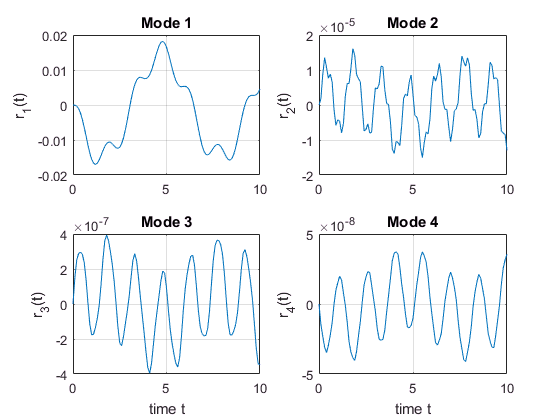

% System dynamics:
omeg = bsol1(2:N+1).^2; % eigen frequencies
D2psi = (diff(psiarr',2)/h^2)';
marr = D2psi(:,1)'./(omeg.^2);
A = [0 1 zeros(1,2*N);                               % Dtheta
    0 0 b*kron(marr.*omeg.^2,[1 0])];                % D2theta
for i=1:N
    tmprow = [0 0 zeros(1,2*i-1) 1 zeros(1,2*(N-i))  % Dr_i
        0 0 -b*marr(i)*kron(marr.*omeg.^2,[1 0])];   % D2r_i
    tmprow(2,1+2*i) = tmprow(2,1+2*i) - omeg(i)^2;   % D2r_i (direct state influence)
    A = [A;tmprow];
end
B = [0;1;-kron(marr',[0;1])];
% Time simulation:
z0 = zeros(2*(N+1),1);
u = @(t)(0.1*sin(t));%(torque1(t))
fdyn = @(t,z)(A*z+B*u(t));
[time,zsol] = ode45(fdyn,0:0.1:10,z0);
% Test vibration components:
figure; 
subplot(2,2,1); plot(time,zsol(:,1+2*1))
grid; ylabel('r_1(t)'); title('Mode 1')
subplot(2,2,2); plot(time,zsol(:,1+2*2))
grid; ylabel('r_2(t)'); title('Mode 2')
subplot(2,2,3); plot(time,zsol(:,1+2*3))
grid; xlabel('time t'); ylabel('r_3(t)'); title('Mode 3')
subplot(2,2,4); plot(time,zsol(:,1+2*4))
grid; xlabel('time t'); ylabel('r_4(t)'); title('Mode 4')

Overall deformation:


$$y(x,t)=\overset{\infty}{\underset{i=1}{\sum}}\psi_i(x)r_i(t)\approx\overset{N}{\underset{i=1}{\sum}}\psi_i(x)r_i(t)$$


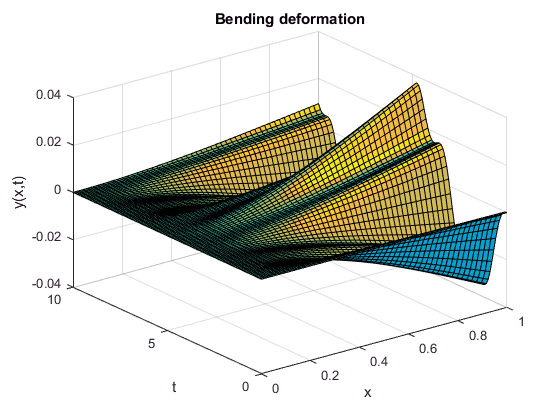

% 3D deformation plot:
rsol = zsol(:,3:2:end-1)';
time = time';
y = zeros(length(time),length(X));
for j=1:length(time) % build over time
    tmpcol = sum(diag(rsol(:,j))*psiarr);
    y(j,:) = tmpcol;
end
figure; surfl(X,time,y); %shading flat
xlabel('x'); ylabel('t'); zlabel('y(x,t)'); title('Bending deformation')

Total flexible arm movement (see figure):


$$(X,Y)=\big[x\cos(\theta(t))-y(x,t)\sin(\theta(t))\,,\,x\sin(\theta(t))+y(x,t)\cos(\theta(t))\big]$$


Error using sym>tomupad (line 1229)
Conversion to 'sym' from 'struct' is not possible.

Error in sym (line 179)
                S.s = tomupad(x);

Error in sym/privsubsasgn (

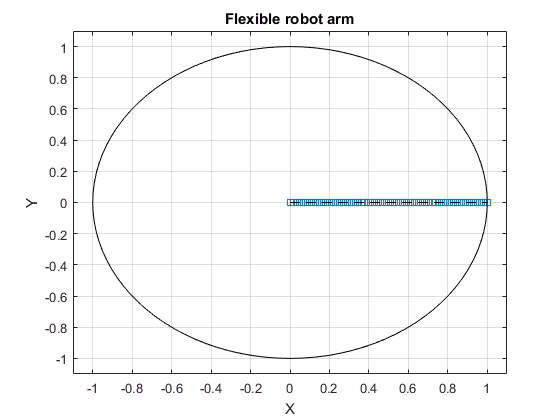

% Cartesian representation:
thetasol = zsol(:,1)'; % rotational transformation (over time)
Xcart = zeros(length(time),length(X)); Ycart = zeros(length(time),length(X));
Xnom = zeros(length(time),length(X)); Ynom = zeros(length(time),length(X));
for j=1:length(time) % build over time    
    Xcart(j,:) = X*cos(thetasol(j)) - y(j,:)*sin(thetasol(j));
    Ycart(j,:) = X*sin(thetasol(j)) + y(j,:)*cos(thetasol(j));
    Xnom(j,:) = X*cos(thetasol(j));
    Ynom(j,:) = X*sin(thetasol(j));
end
% Flexible arm plot:
for k=1:length(time)
    plot(Xcart(k,:),Ycart(k,:),'--s'); grid
    hold on; plot(Xnom(k,:),Ynom(k,:),'--black'); circle(0,0,1); hold off
    axis([-1.1 1.1 -1.1 1.1])
    xlabel('X'); ylabel('Y'); title('Flexible robot arm')
    MV1(k) = getframe; % movie structure: [figure; movie(MV1)]
end

% Check end effector position:
eflength = sqrt(Xcart(:,end).^2+Ycart(:,end).^2);
figure; plot(time,eflength); grid
xlabel('t'); ylabel('L'); title('End effector length')

COMMENT: By definition large deformations make the arm virutally longer.

## Unconstrained mode method

Approach: $u(t)=0$


$$\theta(t)=:\eta(t)+b\gamma\,q(t)\\
y(x,t):=\phi(x)q(t)$$


where parameter $\gamma$ such that:


$$e\gamma+\int_0^1x\phi(x)dx+c\phi(1)=0$$


This results in the system:


$$e\ddot\eta(t)=u(t)=0\\
\phi''''(x)q(t)+x\big(\ddot\eta(t)+b\gamma\ddot q(t)\big)+\phi(x)\ddot q(t)=0$$



$$\Rightarrow\quad\frac{\phi''''(x)}{b\gamma x+\phi(x)}=-\frac{\ddot q(t)}{q(t)}\quad\overset{!}{=}\quad\omega^2$$


With function $\Phi(x):=\phi(x)+b\gamma x$ the problem results in:


$$\ddot q(t)+\omega^2q(t)=0\\
\Phi''''(x)-\omega^2\Phi(x)=0$$


subject to the boundary conditions:


$$\Phi(0)=\Phi''(1)=0\\
\Phi'(0)=b\gamma\,,\quad b\Phi''(0)=-\omega^2\Phi'(0) ?\\
\Phi'''(1)=-c\omega^2\Phi(1)$$


[...] $\Rightarrow$ eigen function solution for $\delta^4:=\omega^2$ and constant $\alpha$:


$$\phi(x)=\alpha\Big[-2b\delta\big(\sinh(\delta)+\sin(\delta)\big)x+b\big(\sinh(\delta)+\sin(\delta)\big)\big(\sinh(\delta x)+\sin(\delta x)\big)\\\qquad
-\delta^3\big(\sinh(\delta)+\sin(\delta)\big)\big(\cosh(\delta x)-\cos(\delta x)\big)\\\qquad
+\big[b\big(-\sinh(\delta)+\sin(\delta)\big)+\delta^3\big(\cosh(\delta)+\cos(\delta)\big)\big]\big(\sinh(\delta x)-\sin(\delta x)\big)
\Big]$$


% Eigenvalues:
syms delta
charcalc = @(delta)((-c*delta^4+b)*(sin(delta)*cosh(delta)-cos(delta)*sinh(delta)) + ...
    delta^3*(1+cos(delta)*cosh(delta))+2*b*c*sin(delta)*sinh(delta));
epsilon = 1e-3; % numeric accuracy
bsmp = 1:1:200; % samples
bsol = 0; % storage
for i=1:length(bsmp)
    tmp = fzero(charcalc,bsmp(i));
    if (tmp>bsol(end)+epsilon)
        bsol = [bsol tmp];      
    end
end
% Eigenfunction by analytic considerations:
h = 2e-2; % step size
N = 9; % degree of discretizitaion
X = 0:h:1;
phians = @(x,delta)(-2*b*delta.*(sinh(delta)+sin(delta)).*x+b*(sinh(delta)+sin(delta)).*(sinh(delta.*x)+sin(delta.*x)) ...
     -delta.^3.*(sinh(delta)+sin(delta)).*(cosh(delta.*x)-cos(delta.*x)) ...
     +(b*(-sinh(delta)+sin(delta))+delta.^3.*(cosh(delta)+cos(delta))).*(sinh(delta.*x)-sin(delta.*x)));
figure; hold on
for i=1:5
    be = bsol(i+1);
    tmpnorm = sqrt(integral(@(x)(phians(x,be).^2),0,1));
    plot(X,phians(X,be)/tmpnorm)
end
legend('i=1','i=2','i=3','i=4','i=5')
grid; xlabel('x'); ylabel('\phi_i(x)'); title('Eigenmodes - analytic'); hold off

phinorm = sqrt(integral(@(x)(phians(x,bsol(2:N+1)').^2),0,1,'ArrayValued',true));
phiarr = phians(X,bsol(2:N+1)')./phinorm; %zeros(N,length(X));

The respective infinite sum solutions:


$$\theta(t)=\eta(t)+b\overset{\infty}{\underset{i=1}{\sum}}\gamma_iq_i(t)\,,\quad y(x,t)=\overset{\infty}{\underset{i=1}{\sum}}\phi_i(x)q_i(x)$$


with the infinite dimensional ODE system:


$$e\ddot\eta=u(t)\\
\ddot q_j(t)+\omega_j^2q_j(t)=m_j\,u(t)\,,\quad m_j:=-\frac{\phi_j''(0)}{\omega_j^2}$$


This results in the following state space form for $z=[\eta\,,\,\dot\eta\,,\,q_1\,,\,\dot q_1\,,\,\ldots\,,\,q_N\,,\,\dot q_N]^T$:


$$A =\pmatrix{0&1&0&0&\cdots&0&0 \cr 
0&0&0&0&\cdots&0&0 \cr
0&0&0&1&\cdots&0&0 \cr
0&0&-\omega_1^2&0&\cdots&0&0 \cr
\vdots&\vdots&\vdots&\vdots&\ddots&\vdots&\vdots \cr
0&0&0&0&\cdots&0&1 \cr
0&0&0&0&\cdots&-\omega_N^2&0} 
\,,\quad
B =\pmatrix{0 \cr 1/e \cr 0 \cr m_1 \cr \vdots \cr 0 \cr m_N}$$


% System dynamics:
omeg = bsol1(2:N+1).^2; % eigen frequencies
D2phi = (diff(phiarr',2)/h^2)';
marr = -D2phi(:,1)'./(omeg.^2);
A = blkdiag([0 1;0 0],kron(-diag(omeg.^2),[0 0;1 0])+kron(eye(N),[0 1;0 0]));
B = [0;1/e;kron(marr',[0;1])];
% Time simulation:
z0 = zeros(2*(N+1),1);
u = @(t)(0.1*sin(t));%(torque1(t))
fdyn = @(t,z)(A*z+B*u(t));
[time,zsol] = ode45(fdyn,0:0.2:20,z0);
% Test vibration components:
figure; 
subplot(2,2,1); plot(time,zsol(:,1+2*1))
grid; ylabel('r_1(t)'); title('Mode 1')
subplot(2,2,2); plot(time,zsol(:,1+2*2))
grid; ylabel('r_2(t)'); title('Mode 2')
subplot(2,2,3); plot(time,zsol(:,1+2*3))
grid; xlabel('time t'); ylabel('r_3(t)'); title('Mode 3')
subplot(2,2,4); plot(time,zsol(:,1+2*4))
grid; xlabel('time t'); ylabel('r_4(t)'); title('Mode 4')

Overall deformation:


$$y(x,t)=\overset{\infty}{\underset{i=1}{\sum}}\phi_i(x)q_i(t)\approx\overset{N}{\underset{i=1}{\sum}}\phi_i(x)q_i(t)$$


% 3D deformation plot:
qsol = zsol(:,3:2:end-1)';
time = time';
y = zeros(length(time),length(X));
for j=1:length(time) % build over time
    tmpcol = sum(diag(qsol(:,j))*phiarr);
    y(j,:) = tmpcol;
end
figure; surfl(X,time,y); %shading flat
xlabel('x'); ylabel('t'); zlabel('y(x,t)'); title('Bending deformation')

Position angle:


$$\theta(t)=\eta(t)+b\overset{\infty}{\underset{i=1}{\sum}}\gamma_iq_i(t)\approx\eta(t)+b\overset{N}{\underset{i=1}{\sum}}\gamma_iq_i(t)$$


with $\gamma_i$ fulfilling:


$$e\gamma_i+\int_0^1x\phi_i(x)dx+c\phi_i(1)=0$$


% Position angle:
etasol = zsol(:,1)';
gammaarr = -(trapz(X,X.*phiarr,2)+c*phiarr(:,end))/e; % trapezoidal integration
thetasol = etasol + b*gammaarr'*qsol;

Total flexible arm movement (see figure):


$$(X,Y)=\big[x\cos(\theta(t))-y(x,t)\sin(\theta(t))\,,\,x\sin(\theta(t))+y(x,t)\cos(\theta(t))\big]$$


% Cartesian representation:
Xcart = zeros(length(time),length(X)); Ycart = zeros(length(time),length(X));
Xnom = zeros(length(time),length(X)); Ynom = zeros(length(time),length(X));
for j=1:length(time) % build over time    
    Xcart(j,:) = X*cos(thetasol(j)) - y(j,:)*sin(thetasol(j));
    Ycart(j,:) = X*sin(thetasol(j)) + y(j,:)*cos(thetasol(j));
    Xnom(j,:) = X*cos(thetasol(j));
    Ynom(j,:) = X*sin(thetasol(j));
end
% Flexible arm plot:
for k=1:length(time)
    plot(Xcart(k,:),Ycart(k,:),'--s'); grid
    hold on; plot(Xnom(k,:),Ynom(k,:),'--black'); circle(0,0,1); hold off
    axis([-1.1 1.1 -1.1 1.1])
    xlabel('X'); ylabel('Y'); title('Flexible robot arm')
    MV2(k) = getframe; % movie structure: [figure; movie(MV2)]
end

## Discussion

Based on: **[BarbieriOzgüner1988]** *Unconstrained and Constrained Mode Expensions for a Flexible Slewing Link*

The constrained expansion represents a limiting case where the beam has an infinite (or very large) hub inertia so that any elastic deformations do not appreciably affect the rigid motion.

# Sensor concept & control design preparation

...